clear
load("tc.mat")

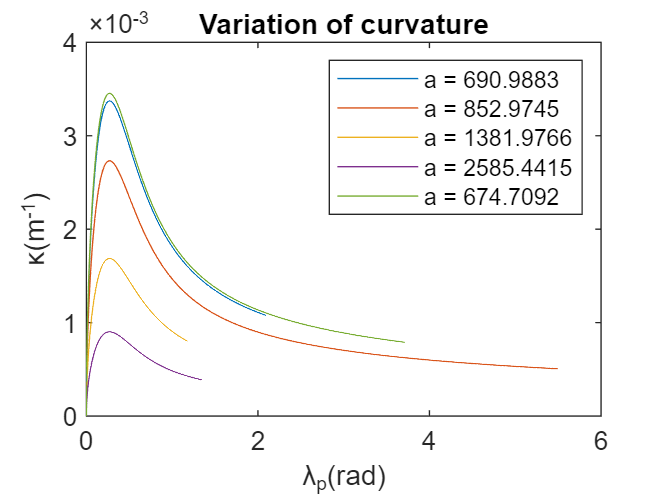

for i = 1:5
%     [tc, lambda0, zeta, v_p, a, delta0, v_r0, v_lam0] = tc_data(i, :)
    tc = tc_data(i, :);
    lambda = linspace(tc.zeta_tc, tc.lambda0_tc, 1000);
    curvature = ((lambda - tc.zeta_tc).^2 + 0.5*1.5)./((tc.a_tc)*(lambda - tc.zeta_tc).^(-0.5).*(0.5*0.5 + (lambda - tc.zeta_tc).^2).^1.5);
    plot((lambda-tc.zeta_tc), curvature, "DisplayName", "a = " + num2str(tc.a_tc));
    hold on
end
xlabel('\lambda_p(rad)');
ylabel('\kappa(m^{-1})')
title("Variation of curvature")
legend
hold off

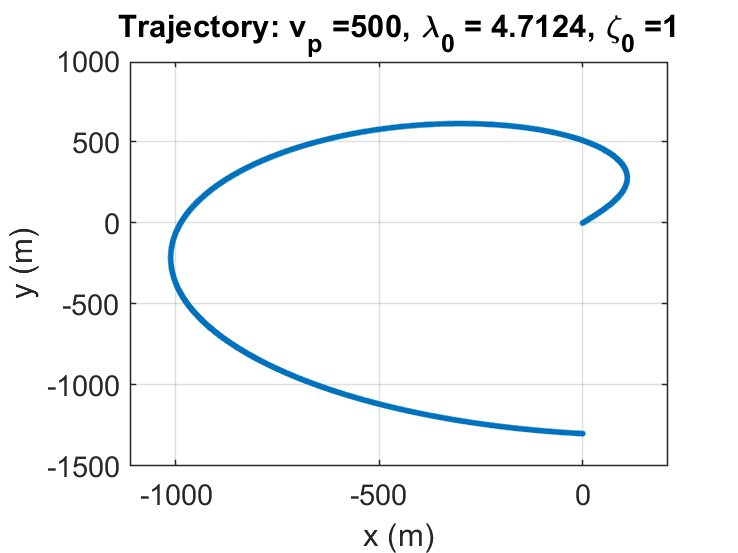

for i = 1:5

    TrajFileName = "./observations/traj/traj_tc" + num2str(i) + ".mat";
    TCFileName = "tc" + num2str(i) + ".mat";
    load(TrajFileName);
    load(TCFileName);
    X = data{1}.Values.data;
    Y = data{2}.Values.data;
    plot(X, Y, ".");
    xlim([min(X)-100 max(X)+100]);
    TitleName = "Trajectory: v_p =" + num2str(v_p) + ", \lambda_0 = " + num2str(lambda0) + ", \zeta_0 =" + num2str(zeta);
    xlabel("x (m)");
    ylabel("y (m)");
    grid("on");
    title(TitleName);
    TrajPlotName = "traj_tc" + num2str(i) + ".png";
    saveas(gcf, TrajPlotName);
    hold off  


end

for i = 1:5
    SimDataFileName = "./observations/sim2_results/sim2_tc" + num2str(i) + ".mat";
    TCFileName = "tc" + num2str(i) + ".mat";
    load(SimDataFileName);
    load(TCFileName);
    timehorizon = data{1}.Values.Time;
    dot_vlambda = data{1}.Values.data;
    lambda_p = data{2}.Values.data;
    r_p = data{3}.Values.data;
    if i ~= 5
        plot(timehorizon(1:end-1), dot_vlambda(1:end-1), '.');
    else
        plot(timehorizon(1:end/2), dot_vlambda(1:end/2), '.');
    end
    LataxTitleName = "Latax: v_p =" + num2str(v_p) + ", \lambda_0 = " + num2str(lambda0) + ", \zeta_0 =" + num2str(zeta);
    ylabel("Lateral Acceleration (m/s^2)");
    xlabel("Time (sec)");
    title(LataxTitleName);
    LataxPlotName = "latax_tc" + num2str(i) + ".png";
    saveas(gcf, LataxPlotName)
    hold off
    if i~=5
        plot(timehorizon(1:end-1), r_p(1:end-1), '.');
    else
        plot(timehorizon(1:end/2), r_p(1:end/2), '.');
    end
    rTitleName = "r_p: v_p =" + num2str(v_p) + ", \lambda_0 = " + num2str(lambda0) + ", \zeta_0 =" + num2str(zeta);
    title(rTitleName);
    ylabel("r_p (m)");
    xlabel("Time (sec)");
    rPlotName = "r_tc" + num2str(i) + ".png";
    saveas(gcf, rPlotName);
    hold off

end

for i = 1:5
    svlFileName = "./observations/svl/svl_tc" + num2str(i) + ".mat";
    TCFileName = "tc" + num2str(i) + ".mat";
    load(TCFileName);
    load(svlFileName);
    s = data{2}.Values.data;
    lambda = data{1}.Values.data;
    plot(lambda, s, '.');
    ylabel('distance (m)');
    xlabel("\lambda_p (rad)");
    svlTitleName = "distance : v_p =" + num2str(v_p) + ", \lambda_0 = " + num2str(lambda0) + ", \zeta_0 =" + num2str(zeta);
    title(svlTitleName);
    svlPlotName = "svl_tc" + num2str(i) + ".png";
    saveas(gcf, svlPlotName);
    hold off
end
   

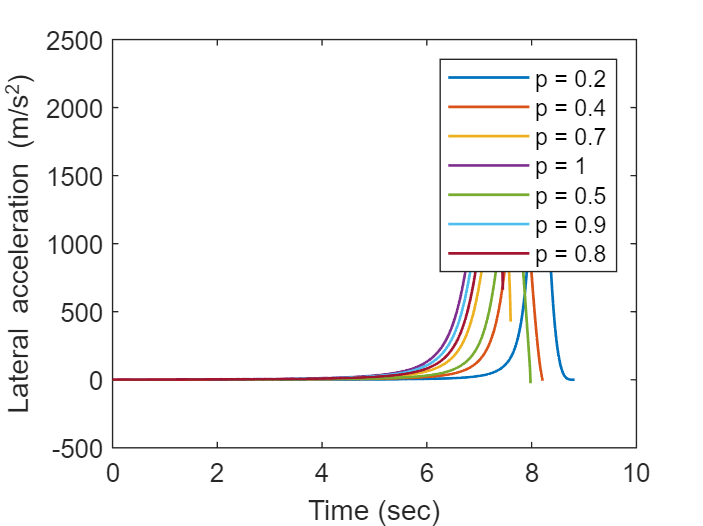

clear
p_arr = [0.2 0.4 0.7 1 0.5 0.9 0.8];
for i = 1:7
    lataxFileName = "./observations/latax_generalized/latax_" + num2str(i) + ".mat";
    data = load(lataxFileName);
    p = p_arr(i);
    timehorizon = data.ans.Time(1:end-1);
    latax = data.ans.Data(1:end-1);
    plot(timehorizon, latax, 'LineWidth', 1, 'DisplayName', ("p = " + num2str(p)));
    hold on
end  
xlabel('Time (sec)');
ylabel('Lateral acceleration (m/s^2)');
legend
hold off